Nsym = 6;           % Filter span in symbol durations
betas = [0.1:0.2:0.9];         % Roll-off factor
beta = betas(1);
sampsPerSymVec = [8,16, 32];
sampsPerSym = sampsPerSymVec(1);    % Upsampling factor
% Parameters
DataL = 20;             % Data length in symbols
R = 1000;               % Data rate
Fs = R * sampsPerSym;   % Sampling frequency
% Create a local random stream to be used by random number generators for
% repeatability
hStr = RandStream('mt19937ar', 'Seed', 0);
% Generate random data
x = 2*randi(hStr, [0 1], DataL, 1)-1;
% Time vector sampled at symbol rate in milliseconds
tx = 1000 * (0: DataL - 1) / R;
to = 1000 * (0: DataL*sampsPerSym - 1) / Fs;
% Design raised cosine filter with given order in symbols
sqrtRcosTxFlt = comm.RaisedCosineTransmitFilter(...
    'Shape',                  'Square root', ...
    'RolloffFactor',          beta, ...
    'FilterSpanInSymbols',    Nsym, ...
    'OutputSamplesPerSymbol', sampsPerSym);

The data stream is upsampled and filtered at the transmitter using the designed filter. This plot shows the transmitted signal when filtered using the square-root raised cosine filter.

## Plot with TX filter

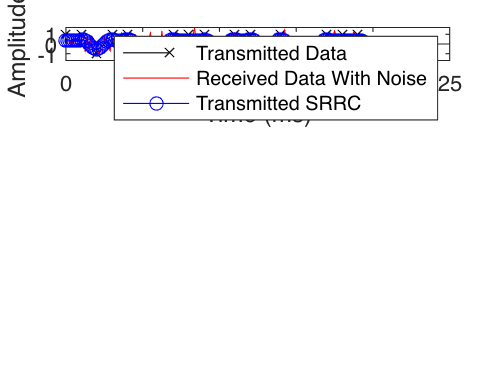

fltDelay = Nsym / (2*R);
% Upsample and filter.
yc = step(sqrtRcosTxFlt, [x; zeros(Nsym/2,1)]);
% Correct for propagation delay by removing filter transients
yc = yc(fltDelay*Fs+1:end);
% Plot data.
%f1 = figure(1);
subplot(3,1,1);
stem(tx, x, 'kx'); hold on;
% Plot filtered data.
ycN = awgn(yc, 5);
plot(to, ycN, 'r-');
plot(to, yc, 'bo-');
hold off;
% Set axes and labels.
axis([0 25 -1.7 1.7]);  xlabel('Time (ms)'); ylabel('Amplitude');
legend('Transmitted Data','Received Data With Noise', 'Transmitted SRRC', 'Location', 'southeast')

## Plot with RX filter

Design and normalize filter.

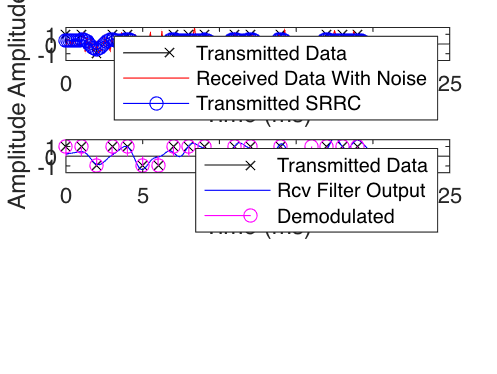

sqrtRcosRxFlt = comm.RaisedCosineReceiveFilter(...
    'Shape',                  'Square root', ...
    'RolloffFactor',          beta, ...
    'FilterSpanInSymbols',    Nsym, ...
    'InputSamplesPerSymbol',  sampsPerSym, ...
    'DecimationFactor',       1);
% Filter at the receiver.
yr = step(sqrtRcosRxFlt, [ycN; zeros(Nsym*sampsPerSym/2, 1)]);
% Correct for propagation delay by removing filter transients
yr = yr(fltDelay*Fs+1:end);
% Plot data.
subplot(3,1,2);
%f2 = figure(2);
stem(tx, x, 'kx'); hold on;
% Plot filtered data.
plot(to, yr, 'b-');
q = downsample(2*(yr>0)-1,sampsPerSym);
stem(tx, q, 'm-'); hold off;
% Set axes and labels.
axis([0 25 -1.7 1.7]);  xlabel('Time (ms)'); ylabel('Amplitude');
legend('Transmitted Data', 'Rcv Filter Output','Demodulated', 'Location', 'southeast')

## Plot without filters

Plot data.

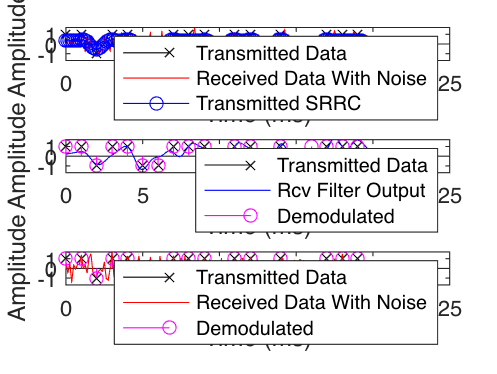

subplot(3,1,3);
%f3 = figure(3);
stem(tx, x, 'kx'); hold on;
% Plot filtered data.
xU = upsample(x,sampsPerSym);
%plot(to, xU, 'b-');
xN = awgn(xU, 5);
plot(to, xN, 'r-');
q = downsample(2*(xN>0)-1,sampsPerSym);
stem(tx, q, 'm-'); hold off;
% Set axes and labels.
axis([0 25 -1.7 1.7]);  xlabel('Time (ms)'); ylabel('Amplitude');
legend('Transmitted Data', 'Received Data With Noise','Demodulated' ,'Location', 'southeast')